clc
clear all

global n; global Y; global y;
sig = 0.15;
m1 =2; m2 = 0; mo = [m1 m2]';

Y = @(t,m) (m(1).*exp(m(2).*t))./sig;
t = [1 2 4 5 8]';
y = [3.2939 4.2699 7.1749 9.3008 20.259]'./sig;

max_iter = 1e6;
tol = 1e-6;

### No. 1 a) Approximate the Jacobian with finite differences.

m = 5; n= 2; 
h = 1e-2;

% Approximated Jacobian
J1 = @(t,m) ((m(1) + h)*exp(m(2)*t) - m(1)*exp(m(2)*t))./(sig*h);
J2 = @(t,m) (m(1)*exp((m(2)+h)*t) - m(1)*exp(m(2)*t))./(sig*h);
J = [J1(t,mo) J2(t,mo)];

% Gaus-Newton method
for k = 1:max_iter
    J = [J1(t,mo) J2(t,mo)];
    dm = -inv(J'*J)*(J'*(Y(t,mo)-y));
    M = mo + dm;
    if norm(M-mo) < tol
        fprintf('Number of iterations taken = %d',k);
        break   
    end
    mo = M;
end

Number of iterations taken = 13

disp(['Resulting parameter estimates are [',num2str(M'),']']);

Resulting parameter estimates are [2.5411      0.2595]


%chi-square
chi_s = 0;
for i = 1:length(t)
    chi_s = chi_s + ((Y(t(i),M)-y(i)))^2;   
end

disp(['chi-square obs = ',num2str(chi_s)])

chi-square obs = 2.8816e-07


% pvalue
p = 1 - chi2cdf(chi_s,m);
disp(['pvalue = ',num2str(p)])

pvalue = 1


Since the value of the p-value is 1, then we reject the null hypothesis, since the fit of the model predictions to the data is almost exact, which is not realistic hence, the parameter estimates are not good.

### 1. b) Report uncertainty estimates: Covariance matrix, confidence intervals, correlation matrix and linearized confidence ellipsoid.

% Covariance matrix
J = [J1(t,M) J2(t,M)];
C = inv(J'*J);
covariance_matrix = C

covariance_matrix =     0.0035   -0.0002
   -0.0002    0.0000


Because $(\sigma_{GN})_{1} (\sigma_{GN})_{2} \ne 0$, then the computed confidence interval doesn't capture the relationship between $m_{1}$ and $m_{2}$

%confidence interval
za = 1.96; % 95% confidence interval

% first parameter
s1 = sqrt(C(1,1)); % standard deviation

% confidence intervals 
c1 = M(1) - za*s1;
c2 = M(1) + za*s1;

cofidence_interval_first = [c1 c2]

cofidence_interval_first =     2.4256    2.6565


% Second parameter
s2 = sqrt(C(2,2)); % standard deviation

% confidence intervals 
c11 = M(2) - za*s2;
c22 = M(2) + za*s2;

cofidence_interval_second = [c11 c22]

cofidence_interval_second =     0.2534    0.2656


The estimates lie with in the confidence interval.

%Correlation matrix
rho1 = C(1,1)/sqrt(C(1,1)*C(1,1));
rho12 = C(1,2)/sqrt(C(1,1)*C(2,2));
Correlation_matrix = [rho1 rho12;rho12 rho1]

Correlation_matrix =     1.0000   -0.9631
   -0.9631    1.0000


The two model parameters are highly negatively statically dependent and correlated, meaning the projection os needle-like with its long principle axis having a negative slope.

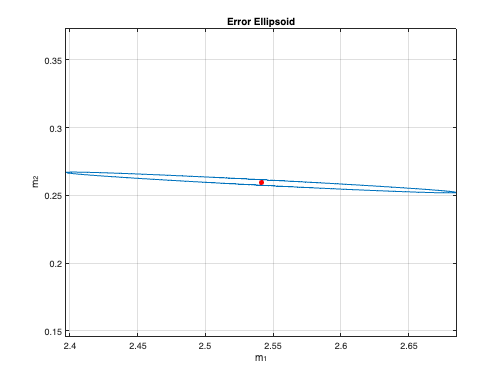

%Linearised ellipsoid
Delta = chi2inv(0.95,2); %Delta2

figure(1)
plot_ellipse(Delta,C,M); hold on 
plot(M(1),M(2),'.r',MarkerSize=17)
grid on
title('Error Ellipsoid')
xlabel('m_1'); ylabel('m_2')

The values of the estimates lie at the center of the ellipsoid, which implies that the estimates lie with in the confidence region.

### N0.2 Use Levenberg-Marquardt method to fit the data.

m1 = 1.7; m2 = 0; 
tol = 1e-6;
lam = 0.4;
disp(['The values of the lamba used is ',num2str(lam)]);

The values of the lamba used is 0.4


%Levenberg-Marquardt method (using the exact Jacobian)
M = lm(mo, sig, t, lam, tol,max_iter);

Number of iterations taken = 1


disp(['Resulting parameter estimates are [',num2str(M'),']']);

Resulting parameter estimates are [2.5411      0.2595]


%chi-square
chi_s = 0;
for i = 1:length(t)
    chi_s = chi_s + ((Y(t(i),M)-y(i)))^2;   
end

disp(['chi-square obs = ',num2str(chi_s)])

chi-square obs = 2.8813e-07


% pvalue
p = 1 - chi2cdf(chi_s,m);
disp(['pvalue = ',num2str(p)])

pvalue = 1


Since the value of the p-value is 1, then we reject the null hypothesis, since the fit of the model predictions to the data is almost exact, which is not realistic hence, the parameter estimates are not good.

### b). Choose initial parameter estimates m1 = 1.6, m2 = 0, and through trial and error find two values of λ, of different orders of magnitude, for which the solution converges.

m1 = 1.6; m2 =0; mo = [m1 m2]';
lam1 = 90;
lam2 = 0.85;
disp(['The values of the first lamba used is ',num2str(lam1)]);

The values of the first lamba used is 90


%Levenberg-Marquardt method
%M = LM(m1,m2,lam1,t,J1,J2,max_iter,tol)

warning('off','all')

%Levenberg-Marquardt method (using the exact Jacobian)
M = lm(mo, sig, t, lam1, tol,max_iter);

Number of iterations taken = 25

disp(['Resulting parameter estimates are [',num2str(M'),']']);

Resulting parameter estimates are [2.5411      0.2595]


disp(['The values of the second lamba used is ',num2str(lam2)]);

The values of the second lamba used is 0.85


M = lm(mo, sig, t, lam2, tol,max_iter);

Number of iterations taken = 2001

%M = LM(m1,m2,lam2,t,J1,J2,max_iter,tol)
disp(['Resulting parameter estimates are [',num2str(M'),']']);

Resulting parameter estimates are [-0.043585      9.9126]


The number of iterations taken for the code to converge depends on the value of $\lambda$ chosen. 

function m = lm(mo, sig, t, lam, tol,max_iter)
    global n; global Y; global y;
    J = @(t,m) [(exp(m(2).*t))./sig (m(1).*t.*exp(m(2).*t))./sig]; %exact jacobian
   
    for k = 1:max_iter
        dm = -inv(J(t,mo)'*J(t,mo) + lam*eye(n))*J(t,mo)'*(Y(t,mo)-y);
        m = mo + dm;
        if norm(m-mo) < tol
            fprintf('Number of iterations taken = %d',k);
            break   
        end
        mo = m;
        
    end
end

function [M] = LM(m1,m2,lam,t,J1,J2,max_iter,tol)
    global n; global Y; global y;
    mo = [m1 m2]';
    for k = 1:max_iter
        J = [J1(t,mo) J2(t,mo)];  %approximate jacobian
        dm = -(J'*J + lam.*eye(n))\(J'*(Y(t,mo)-y));
        M = mo + dm;
        if norm(M-mo) < tol
            fprintf('Number of iterations taken = %d',k);
            break   
        end
        mo = M;
    end
end

function plot_ellipse(DELTA2,C,m)
n=5000;

%construct a vector of n equally-spaced angles from (0,2*pi)
theta=linspace(0,2*pi,n)';

%corresponding unit vector
xhat=[cos(theta),sin(theta)];
Cinv=inv(C);

%preallocate output array
r=zeros(n,2);
for i=1:n
%store each (x,y) pair on the confidence ellipse in the corresponding row of r
r(i,:)=sqrt(DELTA2/(xhat(i,:)*Cinv*xhat(i,:)'))*xhat(i,:);
end

% Plot the ellipse and set the axes.
plot(m(1)+r(:,1), m(2)+r(:,2));
axis equal
end